# Lab - 04

format long e

## **Question - 1**

(4/3 - 1)*3 - 1

ans =     -2.220446049250313e-16


5*((1+exp(-50)) - 1)/((1 + exp(-50)) - 1)

ans =    NaN


log(exp(750))/100

ans =    Inf


We observe that the result of the mentioned expressions is same as it is mentioned in the question, the reason to which is catastrophic cancellation, i.e. the blowing up of error due to round-off while evaluating some operator over floating point numbers. 

For example in 1st expression, 4/3 = 1.3333... which on further evaluating, leaves the rounding error -2.2204e-16 instead of a perfect 0. 

In 2nd expression, due to roundoff error, exp(-50) is treated as 0, which makes the expression a 0/0 form giving NaN.

In 3rd expression, again due to roundoff errors, exp(750) blows up to Inf, making it's log to be Inf as well.

## **Question - 2**

p = (1:16)'; x_array = 10.^(-p);

f1 = @(x) (tan(x) - x)./x.^(3);
f2 = @(x) (exp(x) + cos(x) - sin(x) - 2) ./ x.^3;
f3 = @(x) (exp(x) - 1) ./ x;

f1_hat = @(x) 1/3 + 2*x.^2/15 + 17*x.^4/315;
f2_hat = @(x) 1/3 + x/12 + x.^4/2520 + x.^5/20160;
f3_hat = @(x) 1 + x/2 + x.^2/6 + x.^3/24 + x.^4/120;

2 (i)

vals_actual = f1(x_array);
vals_approx = f1_hat(x_array);

E_actual = abs(1/3 - vals_actual);
E_approx = abs(1/3 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -2.873299829331332e+00
     2.000000000000000e+00    -4.875043663184115e+00
     3.000000000000000e+00    -6.874849849102898e+00
     4.000000000000000e+00    -8.496812199889503e+00
     5.000000000000000e+00    -6.339513653567319e+00
     6.000000000000000e+00    -4.587227263120465e+00
     7.000000000000000e+00    -2.608872802071586e+00
     8.000000000000000e+00    -4.771212547196625e-01
     9.000000000000000e+00    -4.771212547196625e-01
     1.000000000000000e+01    -4.771212547196625e-01


[p log10(E_approx)]

ans =      1.000000000000000e+00    -2.873306952774722e+00
     2.000000000000000e+00    -4.875043685162658e+00
     3.000000000000000e+00    -6.875061087690836e+00
     4.000000000000000e+00    -8.875061263620294e+00
     5.000000000000000e+00    -1.087506122745802e+01
     6.000000000000000e+00    -1.287504676278810e+01
     7.000000000000000e+00    -1.487540852414338e+01
     8.000000000000000e+00                      -Inf
     9.000000000000000e+00                      -Inf
     1.000000000000000e+01                      -Inf


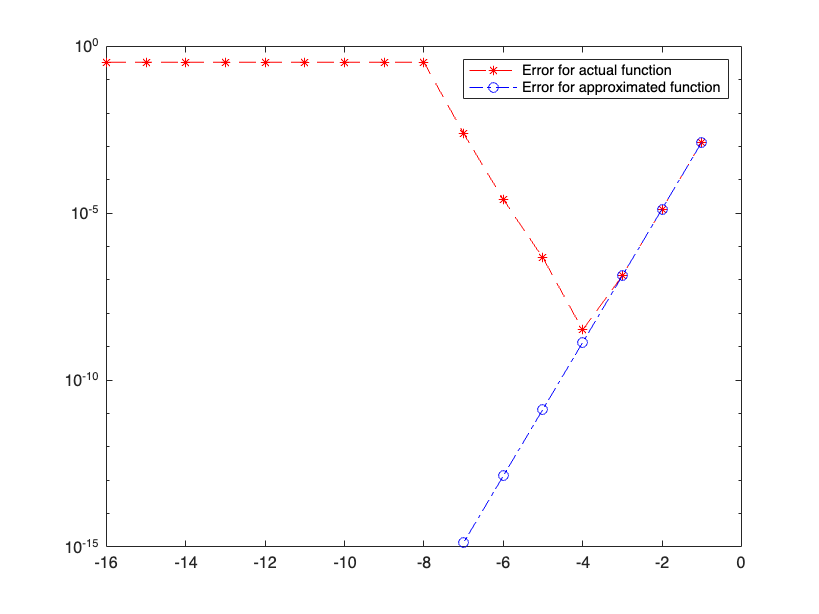


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;

2 (ii)

vals_actual = f2(x_array);
vals_approx = f2_hat(x_array);

E_actual = abs(1/3 - vals_actual);
E_approx = abs(1/3 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -2.079179152122654e+00
     2.000000000000000e+00    -3.079181185832042e+00
     3.000000000000000e+00    -4.078228486147827e+00
     4.000000000000000e+00    -3.750402363212019e+00
     5.000000000000000e+00    -9.556332215736859e-01
     6.000000000000000e+00    -4.771212547196625e-01
     7.000000000000000e+00     5.346440877435310e+00
     8.000000000000000e+00    -4.771212547196625e-01
     9.000000000000000e+00    -4.771212547196625e-01
     1.000000000000000e+01    -4.771212547196625e-01


[p log10(E_approx)]

ans =      1.000000000000000e+00    -2.079179152132846e+00
     2.000000000000000e+00    -3.079181243976963e+00
     3.000000000000000e+00    -4.079181246045648e+00
     4.000000000000000e+00    -5.079181246047673e+00
     5.000000000000000e+00    -6.079181246044779e+00
     6.000000000000000e+00    -7.079181245986920e+00
     7.000000000000000e+00    -8.079181244829726e+00
     8.000000000000000e+00    -9.079181239043763e+00
     9.000000000000000e+00    -1.007918121011394e+01
     1.000000000000000e+01    -1.107918121011394e+01


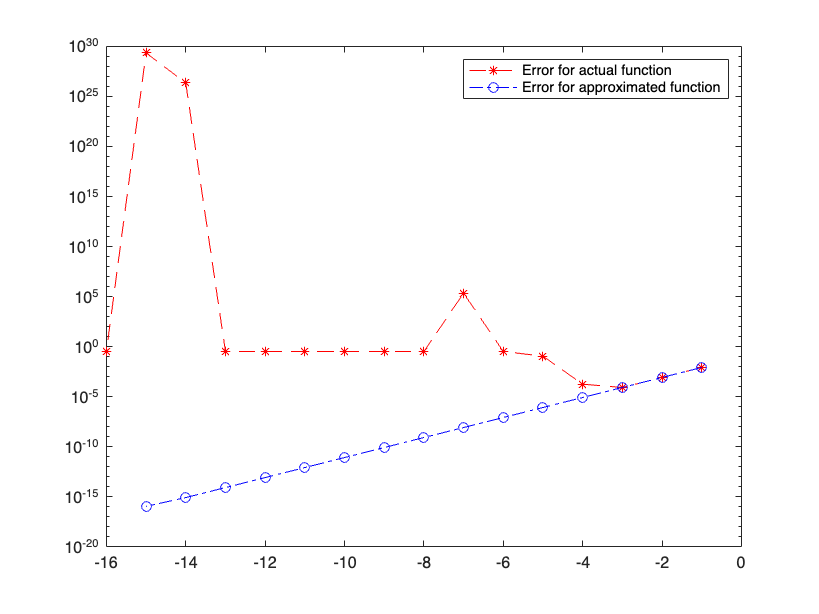


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;

2 (iii)

vals_actual = f3(x_array);
vals_approx = f3_hat(x_array);

E_actual = abs(1 - vals_actual);
E_approx = abs(1 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -1.286432342826650e+00
     2.000000000000000e+00    -2.299581140482518e+00
     3.000000000000000e+00    -3.300885218735133e+00
     4.000000000000000e+00    -4.301015515302865e+00
     5.000000000000000e+00    -5.301029390700364e+00
     6.000000000000000e+00    -6.301062843767653e+00
     7.000000000000000e+00    -7.305977055789310e+00
     8.000000000000000e+00    -8.216277106889963e+00
     9.000000000000000e+00    -7.082282536105524e+00
     1.000000000000000e+01    -7.082282536105524e+00


[p log10(E_approx)]

ans =      1.000000000000000e+00    -1.286432461164006e+00
     2.000000000000000e+00    -2.299581140493628e+00
     3.000000000000000e+00    -3.300885218772343e+00
     4.000000000000000e+00    -4.301015519059760e+00
     5.000000000000000e+00    -5.301028548015156e+00
     6.000000000000000e+00    -6.301029850761315e+00
     7.000000000000000e+00    -7.301029980945499e+00
     8.000000000000000e+00    -8.301029998303393e+00
     9.000000000000000e+00    -9.301029959730297e+00
     1.000000000000000e+01    -1.030102995973030e+01


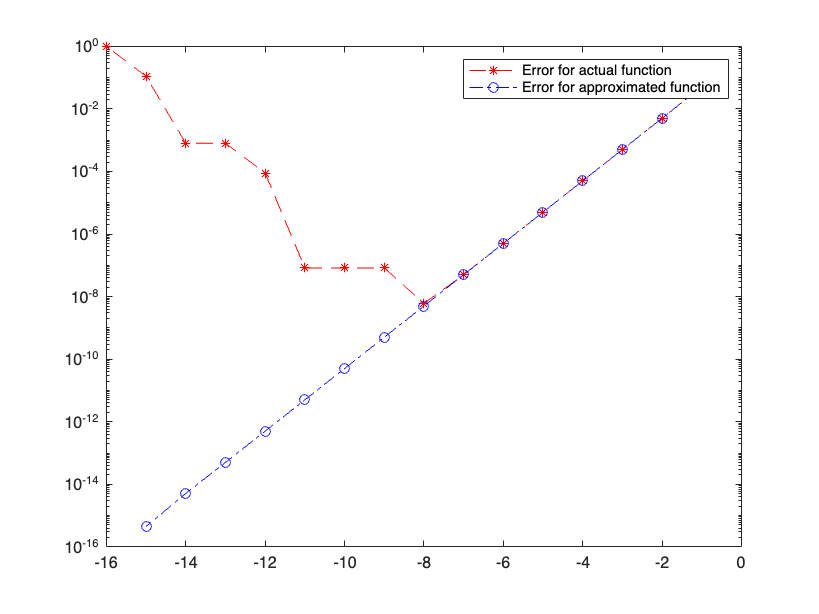


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;